# Lecture 18

## Exercise 6

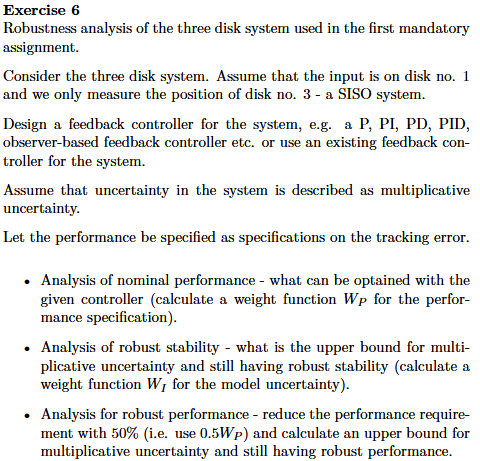

clear all; clc;

syms f_theta1 f_theta2 f_theta3 f_u1 f_u2 theta1 omega1 theta2 omega2 theta3 omega3 u1 u2 y1 y2 y3

load('ECP_values.mat');

J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad

x = [theta1 omega1 theta2 omega2 theta3 omega3].';
u = [u1 u2].';
y = [y1 y2 y3].';
f = [f_theta1 f_theta2 f_theta3 f_u1 f_u2].';
A = [0, 1, 0, 0, 0, 0;
     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0;
     0, 0, 0, 1, 0, 0;
     (k_1/J_1), 0, -(k_1 + k_2)/J_1, (-b_2/J_1), -k_2/J_1, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, -k_2/J_1, 0, k_2/J_1, b_3];
B = [0 0
     1/J_1 0
     0 0
     0 0
     0 0
     0 0];
C = [0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 1 0];
D = [0];
E_x = [0 -1/J_1 0 0 0 0].';
E_x2 = [0 0 0 0 0 0].';
E_y = zeros(3,1);
F_x = [zeros(6, 3), B];
F_y = [eye(3) zeros(3, 2)];

sys_ss = ss(A,B,C,D);
sys_tf = tf(sys_ss);
sys_tf = sys_tf(3,1);

pole(sys_tf)

ans =   -0.1698 +56.3527i
  -0.1698 -56.3527i
  37.7032 + 0.0000i
 -37.7348 + 0.0000i
  -0.4503 +24.1449i
  -0.4503 -24.1449i


Unstable :((

Mc = ctrb(A,B);

if rank(Mc) >= size(A,1)
	disp('System is controllable!');
else
	disp('System is NOT controllable!');
end

System is controllable!


Mo = obsv(A,C);

if rank(Mo) >= size(A,1)
	disp('System is observable!');
else
	disp('System is NOT observable!');
end

System is observable!


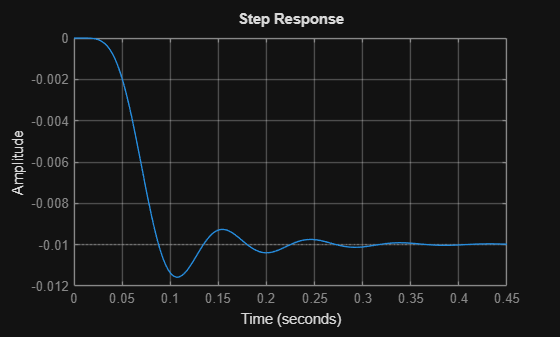

R = 1/10;
Q = C'*C * 1000;
[K, S, P] = lqr(A, B, Q, R);
A_cl = A - B*K;
B_cl = B(:,1);
C_cl = C(3,:);
D_cl = 0;
sys_cl = ss(A_cl, B_cl, C_cl, D_cl);
step(sys_cl)
grid on

Adding integral part

C_out = C(3,:);   % θ₃ output
B_in = B(:,1);    % u₁ input

A_aug = [A, zeros(6,1); -C_out, 0];   % 7x7
B_aug = [B_in; 0];    

Mc = ctrb(A_aug,B_aug);

if rank(Mc) >= size(A_cl,1)
	disp('System is controllable!');
else
	disp('System is NOT controllable!');
end

System is controllable!



Q = C'*C * 100000;
Q_aug = blkdiag(Q, 1);   % Penalize integral error heavily
R = 10000;
K_aug = lqr(A_aug, B_aug, Q_aug, R);

Kx = K_aug(1:6);
Ki = K_aug(7);

A_cl = [A - B_in*Kx,    -B_in*Ki;
        C_out,          0];               % 7x7
B_cl = [zeros(6,1); 1];                   % input: step ref
C_cl = [C_out, 0];                        % output = θ₃
D_cl = 0;

sys_cl = ss(A_cl, B_cl, C_cl, D_cl);
eig(A_cl)

ans =   -1.2183 +56.4645i
  -1.2183 -56.4645i
 -38.0717 + 2.2863i
 -38.0717 - 2.2863i
  -6.1794 +25.1258i
  -6.1794 -25.1258i
   0.0017 + 0.0000i


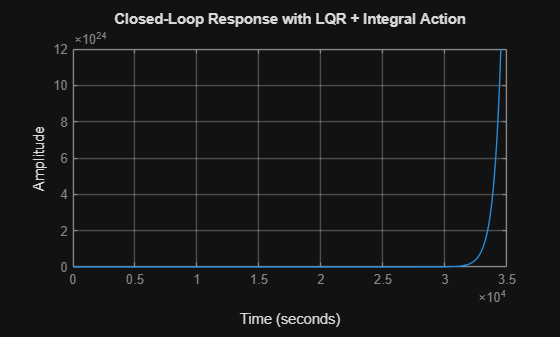


step(sys_cl)
title('Closed-Loop Response with LQR + Integral Action');
grid on


Mc_aug = ctrb(A_aug, B_aug);
rank(Mc_aug) % Should be 7

ans = 7

## Exercise 7

Unrecognized function or variable 'sys1c'.

## Exercise 8.12 -> Actually 8.13

syms K
s = tf('s');

G = (s - 10) / ((s + 1)*(s + 10));
We = 1 / (s + 0.001);
Wu = (s + 2) / (s + 10);


## Exercise 8.21 -> Actually ??

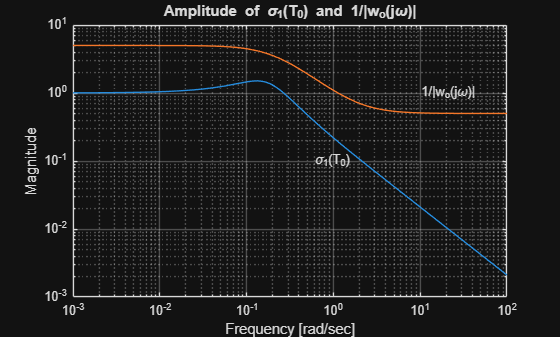

w = logspace(-3,2,100);
g0 = [-87.8 1.4; -108.2 -1.4];
k0 = [-0.0015 0; 0 -0.075];
for j=1:100
    s = i*w(j);
    g = 1/(75*s+1)*g0;
    k = (1+75*s)/s*k0;
    wi = (s+.2)/(0.5*s+1);
    m0 =(eye(2)+g*k)^(-1)*g*k;
    m = wi*m0;
    magm0(j) = max(svd(m0));
    magw(j) = abs(1/wi);
    magm(j) = max(svd(m));
end
figure(1)
loglog(w,magm0,w,magw)
title('Amplitude of \sigma_1(T_0) and 1/|w_o(j\omega)|')
xlabel('Frequency [rad/sec]')
ylabel('Magnitude')
grid
text(.6,.1,'\sigma_1(T_0)')
text(10,1,'1/|w_o(j\omega)|')
print -deps Robust_ex_8_21_fig1.ep
print -dpdf Robust_ex_8_21_fig1.pdf

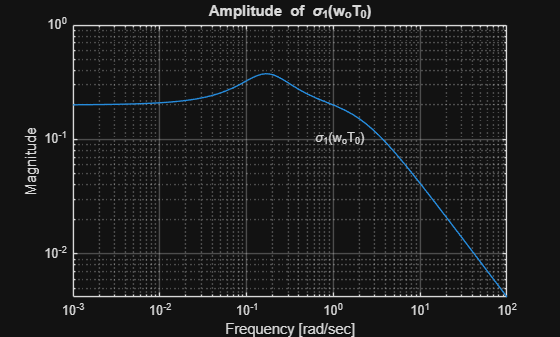

figure(2)
loglog(w,magm)
grid
title('Amplitude of \sigma_1(w_oT_0)')
xlabel('Frequency [rad/sec]')
ylabel('Magnitude')
text(.6,.1,'\sigma_1(w_oT_0)')
print -deps Robust_ex_8_21_fig2.eps
print -dpdf Robust_ex_8_21_fig2.pd

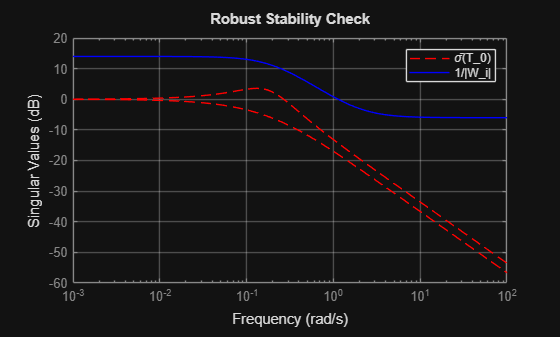

s = tf('s');

% Define plant G(s)
g0 = [-87.8 1.4; -108.2 -1.4];
G = g0 * (1/(75*s + 1));

% Define controller K(s)
k0 = [-0.0015 0; 0 -0.075];
K = (1 + 75*s)/s * k0;

% Define weighting function W_i(s)
Wi = (s + 0.2)/(0.5*s + 1);

% Compute closed-loop sensitivity functions
L = G*K;                   % Open-loop transfer function
T0 = feedback(L, eye(2)); % T0 = L*(I + L)^-1
WiT0 = Wi * T0;

% Plot σ̄(T0) and 1/|Wi(jw)|
figure;
omega = logspace(-3, 2, 100);
sigma(T0, 'r--', omega); hold on;
sigma(1/Wi, 'b', omega);
legend('\sigmā(T_0)', '1/|W_i|');
title('Robust Stability Check');
grid on;

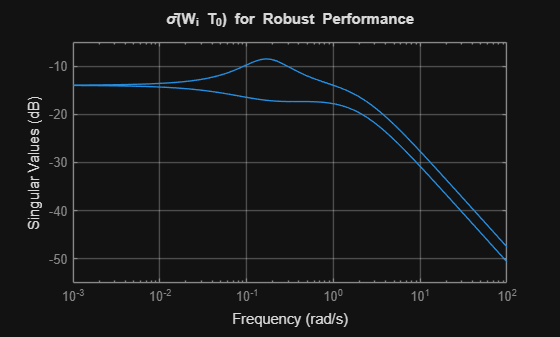


% Plot weighted closed-loop response
figure;
sigma(WiT0, omega);
title('\sigmā(W_i T_0) for Robust Performance');
grid on;